% Create the UAV scenario.
scene = uavScenario("UpdateRate",200,"StopTime",10);

%%%%% OBSTACLES PARAMETERS %%%%%

%%% Ceiling (Soffitto) %%%
l_x_ceil = 1.5; % lato asse x
l_y_ceil = 2.0; % lato asse y
l_z_ceil = 0.2; % lato asse z
ceil_dim = [l_x_ceil,l_y_ceil,l_z_ceil]; 
ceil_color = [1.0 0.8 0.0]; % colore
ceil_p = [1.5 1]; % coordinate del centro dell'ostacolo (rispetto al world frame "ENU")


%%% Supports (Sostegni del soffitto), uguali tra loro %%%
l_x_support = l_x_ceil; 
l_y_support = 0.2;  
l_z_support = 2.4; % == altezza del soffitto. OCCHIO: non farlo troppo vicino alla traiettoria, altrimenti avrai problemi con il ceiling effect
supp_dim = [l_x_support,l_y_support,l_z_support];
supp_color = ceil_color;
support_1_p = ceil_p + [0 (l_y_ceil/2 - l_y_support/2)]; % coordinate del centro del primo support
support_2_p = ceil_p + [0 (-l_y_ceil/2 + l_y_support/2)]; % coordinate del centro del secondo support 


%%% Parallelepipedo %%%
l_z_par = 2.0;
l_x_par = 1.0;
l_y_par = 1.0;
par_dim = [l_x_par,l_y_par,l_z_par];
par_color = [0.196, 0.784, 0.196];
par_p = [4 1];

%%% Struct of obstacles %%%
obs_name = ['ceil','parallelepiped','support_1','support_2'];
obs_p = [ceil_p; par_p; support_1_p; support_2_p];
obs_dim = [ceil_dim; par_dim; supp_dim; supp_dim]; % i sostegni hanno le stesse dimensioni; quindi, hanno lo stesso vettore di dimensioni

obstacles = struct('obstacles', {obs_name}, 'p_obstacles', obs_p,'dim_obstacles', obs_dim);

%%% Ground (Pavimento) %%%
l_x_ground = 6; 
l_y_ground = 4; 
l_z_ground = 0.3; % al di sotto del valore 0;
ground_p = [2 1]; 


%%%%% MESH %%%%%

%%% Ground %%%
addMesh(scene,"Polygon", {[[-l_x_ground/2 -l_y_ground/2] + ground_p; [-l_x_ground/2 l_y_ground/2] + ground_p; [l_x_ground/2 l_y_ground/2] + ground_p; [l_x_ground/2 -l_y_ground/2] + ground_p], [-l_z_ground 0]}, [0.7 0.7 0.7]);

%%% Ceiling %%%
addMesh(scene,"Polygon", {[ceil_p + [-l_x_ceil/2 -l_y_ceil/2]; ceil_p + [-l_x_ceil/2 +l_y_ceil/2]; ceil_p + [+l_x_ceil/2 +l_y_ceil/2]; ceil_p + [+l_x_ceil/2 -l_y_ceil/2]], [l_z_support (l_z_support + l_z_ceil)]}, ceil_color);

% 1st support
addMesh(scene,"Polygon", {[support_1_p + [-l_x_support/2 -l_y_support/2]; support_1_p + [-l_x_support/2 +l_y_support/2]; support_1_p + [+l_x_support/2 +l_y_support/2]; support_1_p + [+l_x_support/2 -l_y_support/2]], [0 l_z_support]}, supp_color);

% 2nd support
addMesh(scene,"Polygon", {[support_2_p + [-l_x_support/2 -l_y_support/2]; support_2_p + [-l_x_support/2 +l_y_support/2]; support_2_p + [+l_x_support/2 +l_y_support/2]; support_2_p + [+l_x_support/2 -l_y_support/2]], [0 l_z_support]}, supp_color);

%%% Parallelepipedo %%%
addMesh(scene,"Polygon", {[par_p + [-l_x_par/2 -l_y_par/2]; par_p + [-l_x_par/2 +l_y_par/2]; par_p + [+l_x_par/2 +l_y_par/2]; par_p + [+l_x_par/2 -l_y_par/2]], [0 l_z_par]}, par_color);

%%% Drone %%%
orientation = quaternion(zeros(size(points,1),size(points,2)),"eulerd","ZYX","frame"); %per far rimanere l'UAV con lo stesso orientamento, convertendo gli angoli in Eulero in matrice di rotazione
traj = waypointTrajectory("Waypoints", [points(:,2) points(:,1) -points(:,3)],"TimeOfArrival",[0:1:10],'Orientation',orientation); %traiettoria che dovrel_x_grounde seguire il drone, avendo conto della configurazione NED
uavPlat = uavPlatform("UAV",scene,"Trajectory",traj); %carica l'UAV con la traiettoria
updateMesh(uavPlat,"quadrotor", {1.0}, [1 0 0],eul2tform([0 0 pi])); %avendo angoli di Eulero con configurazione ZYX, si ruota la mesh del drone di pigreco attorno all'asse x per avere i propeller che puntano in alto

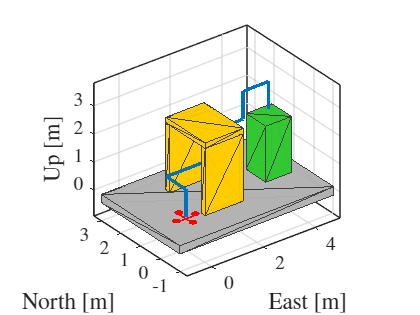

%% PLOTS

f = figure;
hold on
show3D(scene); % scenario plot
plot3(p(1,:),p(2,:),p(3,:), 'LineWidth', 2) % trajectory plot
hold off
%title ('Scenario', 'Interpreter','latex', 'FontSize',14)
xlabel('East [m]','Interpreter','latex')
ylabel('North [m]','Interpreter','latex')
zlabel('Up [m]','Interpreter','latex')
grid on 
box on

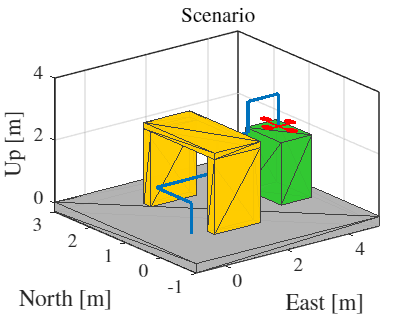


%exportgraphics(f, 'scenario.pdf');


% UAV Animation
figure
setup(scene);
ax = axes;
hold(ax, 'on')
plot3(ax, p(1,:), p(2,:), p(3,:), 'LineWidth', 2);
show3D(scene, "Parent", ax); % primo frame
title(ax, 'Scenario', 'Interpreter','latex', 'FontSize',14)
xlabel(ax, 'East [m]', 'Interpreter','latex')
ylabel(ax, 'North [m]', 'Interpreter','latex')
zlabel(ax, 'Up [m]', 'Interpreter','latex')
grid(ax, 'on')
box(ax, 'on')
while advance(scene)
    show3D(scene, "Parent", ax, "FastUpdate", true);
    drawnow limitrate
end